# testing a pico2 controlled LM317

11Nov24 BR

The circuit has pwm filter made of 2k+10uf --> 20k+1uf --> 2N2222 emitter follower (collector = 3V3 pin) --> 1k + 10kpot --> dual 2N2222. 

A0 = LM317 out  divided by 4.7k+2k for voutmax = 3.13V corresponding to 10.91VDC.

A1 = PWM filter output on emitter follower base. 

Software interface = s25/316/316matlabFiles/pscope2, A0/A1 hasn't been implemented right. 10 bit ADC and DAC.

Added a pause writeline(pico,'d 20'), so the 1000 samples span 48msec. Some low frequency step is visible, about 10msec period. 

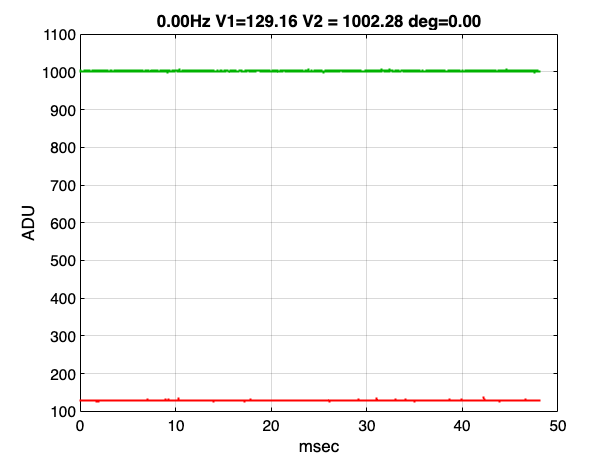

writeline(pico,'p 0'); 
pause(1); 
pwmval = round(linspace(300,1023,50)');
adu2v = 3.3/1023*(4.7+2)/2;
meanv = zeros(50,2);
stdv = meanv;
tic; 
for i=1:50
    writeline(pico,sprintf('p%d',pwmval(i)));
    pause(.1);
    runBtn.UserData = true; % runOnce
    pscope2;
    meanv(i,:) = mean(dat.data);
    stdv(i,:) = std(dat.data);
end

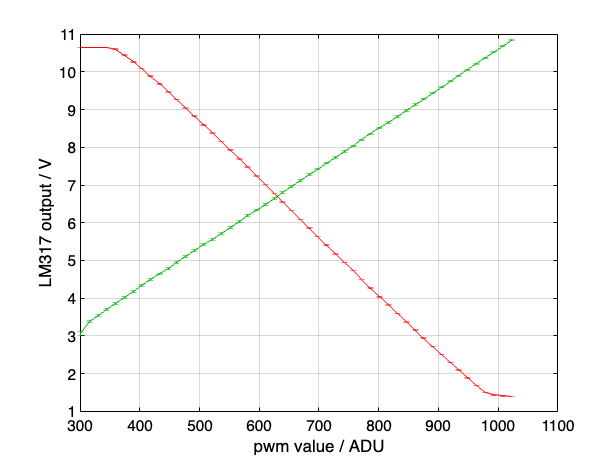

errorbar(pwmval, meanv*adu2v, stdv*adu2v);
xlabel('pwm value / ADU'); ylabel('LM317 output / V'); grid;

writeline(pico,'p 0');
toc

Elapsed time is 18.272149 seconds.


A couple of issues: 1) multiplying A2 by voltage divider above --> error. 2) messed with the pwm caps --> C3 = 22uf tant and C4 --> 2uf (1uf mono + 1uf poly) -- what I have. Time constant is a little longer, see it on std of first point. But these caps lower mean(stdv) from 1.2 6.1 to .71 2.1. The 2nd number is times about 3, so both are <1ADU now. 

Some of the noise is 120Hz from my PS503A power supply at 11.9V -- need to replace filter caps. 

R7+R8 = 1515 ohms measured.

## repeating the measuremnts 

Just to get a sense of variability

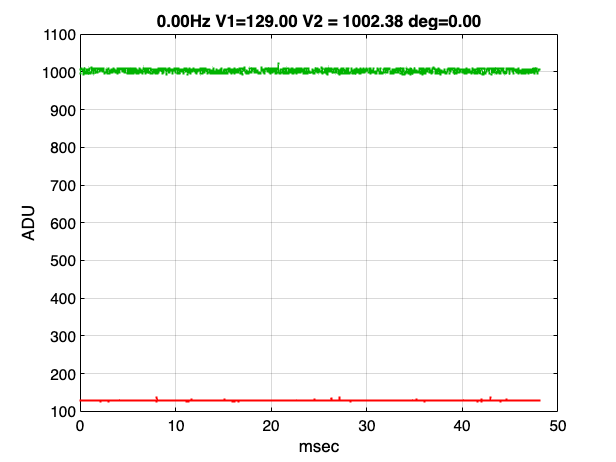

for i=1:50
    writeline(pico,sprintf('p%d',pwmval(i)));
    pause(.1);
    runBtn.UserData = true; % runOnce
    pscope2;
    meanv(i,:) = mean(dat.data);
    stdv(i,:) = std(dat.data);
end

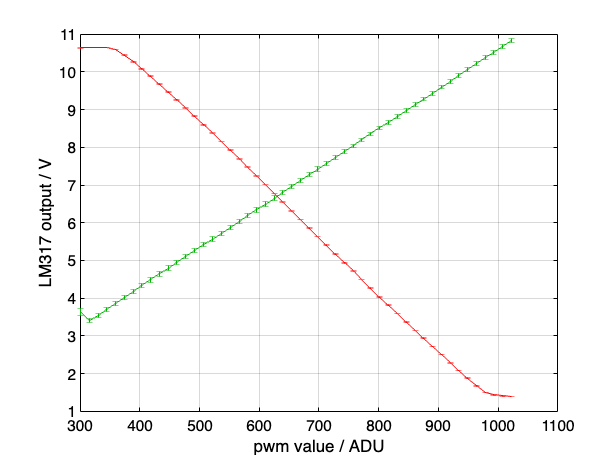

errorbar(pwmval, meanv*adu2v, stdv*adu2v);
xlabel('pwm value / ADU'); ylabel('LM317 output / V'); grid;

## 10 ohm on Q3 emitter

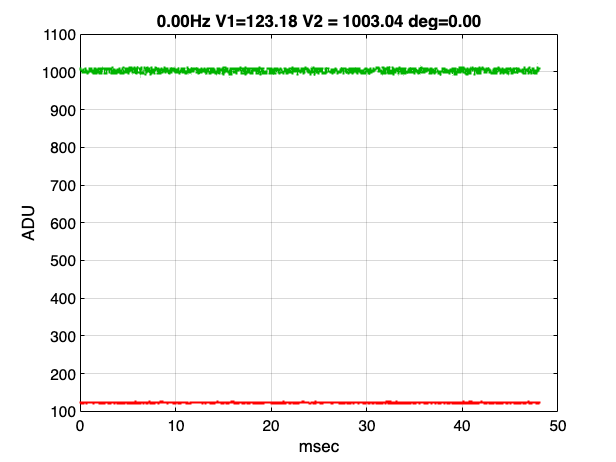

for i=1:50
    writeline(pico,sprintf('p%d',pwmval(i)));
    pause(.1);
    runBtn.UserData = true; % runOnce
    pscope2;
    meanv(i,:) = mean(dat.data);
    stdv(i,:) = std(dat.data);
end

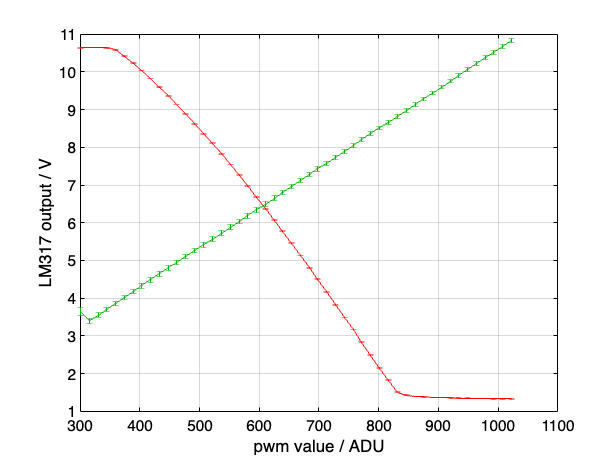

errorbar(pwmval, meanv*adu2v, stdv*adu2v);
xlabel('pwm value / ADU'); ylabel('LM317 output / V'); grid;

So that shows we're multiplying the mirrored current, 

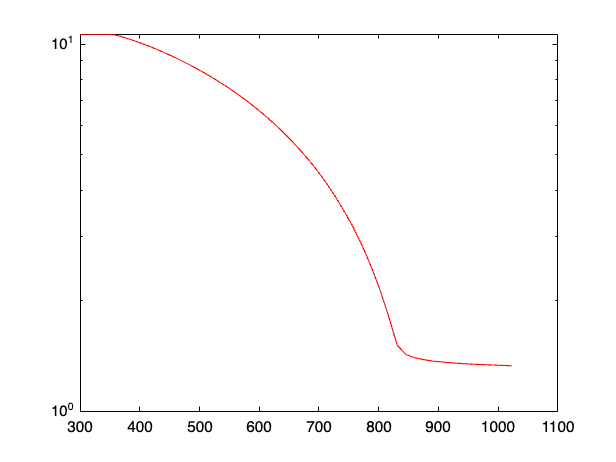

semilogy(pwmval, meanv(:,1)*adu2v)

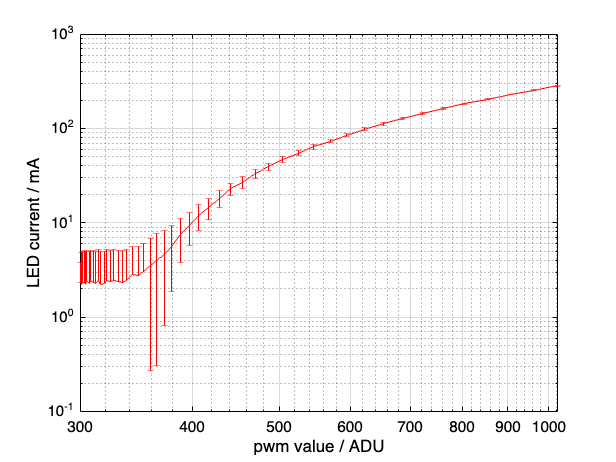

pwmval = round(logspace(log10(10),log10(1023-290),50)')+290;
writeline(pico,sprintf('p%d',pwmval(1))); pause(1);
adu2mA = 3.3/1023*1000/1; % 1 ohm sense resistor
for i=1:50
    writeline(pico,sprintf('p%d',pwmval(i)));
    pause(.05);
    runBtn.UserData = true; % runOnce
    pscope2;
    meanv(i,:) = mean(dat.data);
    stdv(i,:) = std(dat.data);
end
writeline(pico,'p 0');
mmA = meanv(:,1)*adu2mA; smA = stdv(:,1)*adu2mA;
errorbar(pwmval, mmA, smA); 
xlabel('pwm value / ADU'); ylabel('LED current / mA'); grid;
set(gca,'xscale','log'); set(gca,'yscale','log');

The noise at the bottom is bit noise -- not enough current across the 1 ohm resistor to give a good voltage. Swapping to a larger current sense for the lower values would work, but I'm too busy now ... and want to swap out for a higher beta transistor -- the MJE3055 has beta ~ 40. The pwm filter has Z = 22k, the emitter follower load has Z ~ 300 ohms --> need beta > 73 ... 